# **VALIDACIONES LAB#2**

#### **PLANTA #1**


%Primero vamos a Sacar las señales
% primero el nombre de el archivo con el que se exporto la espacio de
% trabajo , en signals(posicion)

t=P1.time; %aqui para tiempo

y=P1.signals(1).values(:); %aqui para la señal de salida
u=P1.signals(2).values(:); %aqui para la señal de entrada
e=P1.signals(2).values(:); %%aqui para la señal de error
%Primera Planta LAB#2
s=tf('s');
G1=1/(0.5*s+1)

G1 =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



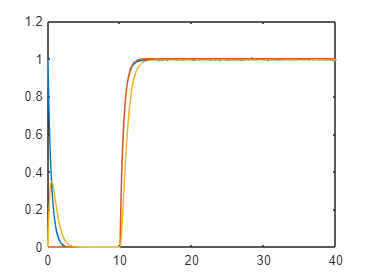


yideal=lsim(G1,u,t); %para poder graficar la funcion de transferencia de el sistema

plot(t,u,'DisplayName','u');hold on;plot(t,y,'DisplayName','y');plot(t,yideal,'DisplayName','yi');hold off;

#### **PLANTA #1 CON RETROALIMENTACION**

t2=P1LCIC.time;%sacamos la variable de tiempo
r2=P1LCIC.signals(2).values(:);%sacamos la señal de entrada
y2=P1LCIC.signals(5).values(:);%sacamos la señal de salida /la señal real
e3=P1LCIC.signals(4).values(:);%sacamos señal de error
G1=feedback(G,1);%Retroalimentamos la funcion de transferencia
yideal2=lsim(G1,r2,t2);%para graficar nuestra funcion de transferencia/salida ideal
plot(t2,r2,'DisplayName','u2');hold on;plot(t2,yideal2,'DisplayName','yi2');plot(t2,y2,'DisplayName','y2');hold off;

#### **PLANTA#2 **

**LAZO ABIERTO**

%Primero vamos a Sacar las señales
% primero el nombre de el archivo con el que se exporto la espacio de
% trabajo , en signals(posicion)

t=P1LA.time; %aqui para tiempo

y=P1LA.signals(1).values(:); %aqui para la señal de salida
u=P1LA.signals(2).values(:); %aqui para la señal de entrada

%Primera Planta LAB#2
s=tf('s');
G1=1/(0.5*s+1)

yideal=lsim(G1,u,t); %para poder graficar la funcion de transferencia de el sistema

plot(t,u,'DisplayName','u');hold on;plot(t,y,'DisplayName','y');plot(t,yideal,'DisplayName','yi');hold off;